clear
close all
clc
addpath([cd '/functions/'])

global HYDRA_SVM_ADC_OUT_BUFF_SIZE
global ADC_WIDTH
global FREQUENCY_CENTRAL
global DATA_RATE

fl_plot_animation = false;

HYDRA_SVM_ADC_OUT_BUFF_SIZE = 1320; % длина строки ГЛ данных
ADC_WIDTH = 12;                     % разрядность АЦП
FREQUENCY_CENTRAL = 3e6;            % центральная частота ЗИ
DATA_RATE = 4 * FREQUENCY_CENTRAL;  % частота дискретизации

base = [24; 58] / 1000;             % расстояния от излучателя до мишеней


%% считываем ГЛ данные
test_data = readmatrix('../data/11.10.2024/adc_565535_15_51COM5.txt');
num_blank = 330;                    % длина интервала бланкирования
start_col = 2;                      % номер столбца начала ГЛ данных в txt-файле

sound_velocity_ini = 1421;          % скорость звука в начале ГЛ данных (1-ая строка)
sound_velocity_tgt = 1505;          % скорость звука в конце ГЛ данных (последняя строка)

% количество считанных строк
[number_line,~] = size(test_data);
% добавляем num_blank пустых точек в начало
test_data = [nan(number_line, num_blank) test_data(:,start_col:end)];

% делаем количество точек в строке кратное 4
mod_4 = mod(size(test_data,2), 4);
if ( mod_4 ~= 0 )
    test_data = [test_data zeros(number_line, 4-mod_4)];
end
% количество считанных строк
[number_line,length_line] = size(test_data);


## Убираем постоянную составляющую в сигнале

Эхо-сигнал с выхода АЦП можно представить в виде

$s\left(t\right)=A_0 \left(t\right)+A_1 \left(t\right)\cdot \sin \left(2\cdot \pi \cdot f_0 \cdot t+\varphi \right)$,

где $A_0 \left(t\right)$ - смещение нуля сигнала ("постоянная" сосавляющая),

      $A_1 \left(t\right)$ - амплитуда синусоидального сигнала,

      $f_0$ - центаральная частота ЗИ,

      $\varphi$ - начальная фаза эхо-сигнала.

В датчике $A_0 \left(t\right)\not= \textrm{const}$, зависит от времени. Смещение нуля сигнала изменяется, оно разное для разных выборок. Т.е. $A_0 \left(t\right)$ - это какое-то низкочастотное (относительно $f_0$) колебание. На рисунке ниже представлен входной сигнал, здесь красные точки это нечётные выборки, а синии - чётные.

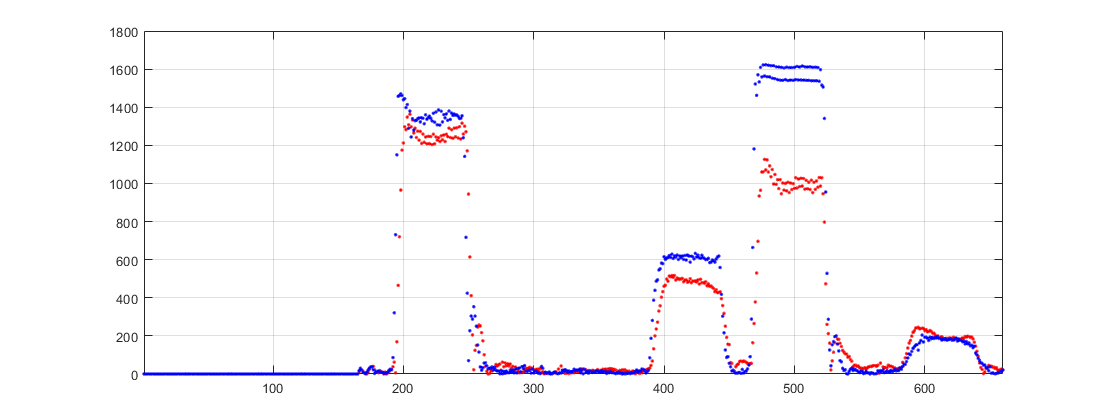

Для дальнейших расчётов мы преобразуем входной сигнал в комплексный вид. В нашем случае это делается соответствующей группировкой действительных выборок, причём нечетные выборки - действительные составляющие комплексного сигнала, а чётные - мнимые. При наличии нескомпенсированной составляющей $A_0 \left(t\right)$ получаемый комплексный сигнал имеет вид (после удаление постоянной составлющей - среднего значения)

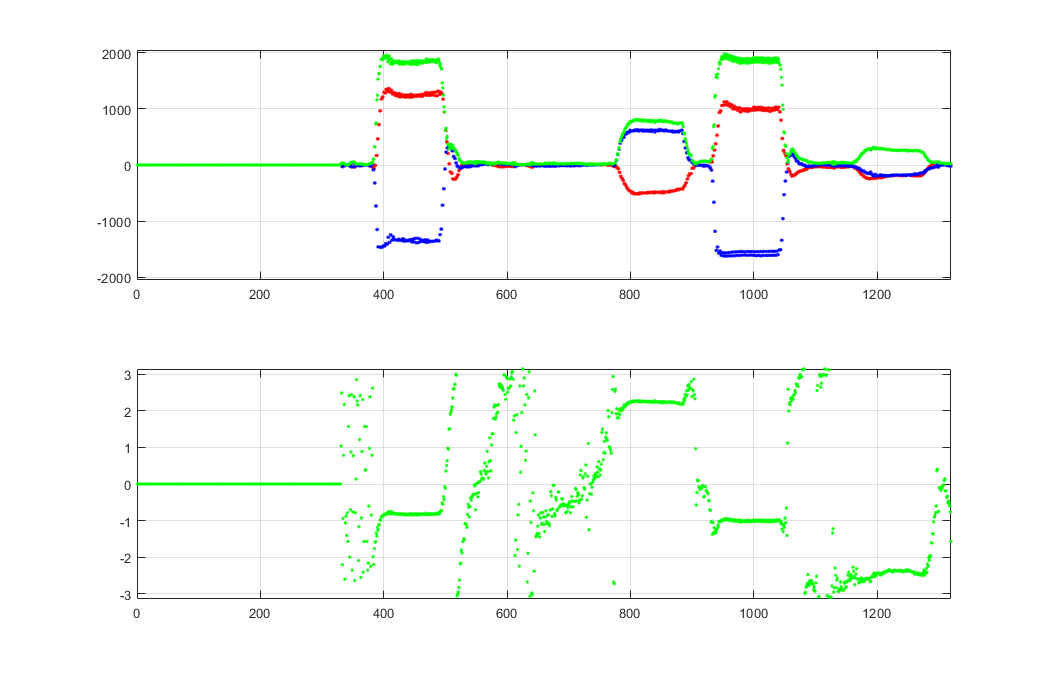

здесь верхний график: красные точки - действительная составляющая

                                       синии точки - мнимая сосавляющая,

                                       зелёные точки -амплитуда,

нижний график - фаза комплексного сигнала.

Для компенсации $A_0 \left(t\right)$  предлагается использовать значения полученные вычислением среднего значения в скользящем окне. Использовалось среднее значение 4 соседних отсчётов.

% offset = double(mean(mean(test_data,2,"omitnan"),"omitnan"));
% test_data = int16(test_data) - offset;

% for kk = 1:number_line
%   offset_1 = int16(movmean(test_data(kk,1:2:end),[0 3]));
%   offset_2 = int16(movmean(test_data(kk,2:2:end),[0 3]));
%   test_data(kk,1:2:end) = test_data(kk,1:2:end) - offset_1;
%   test_data(kk,2:2:end) = test_data(kk,2:2:end) - offset_2;
% end
test_data = int16(test_data);
test_data(:,1:num_blank) = NaN;


Результат значение выборок сигнала после компенсации $A_0 \left(t\right)$ и получаемый комплексный сигнал представлены на рисунках ниже

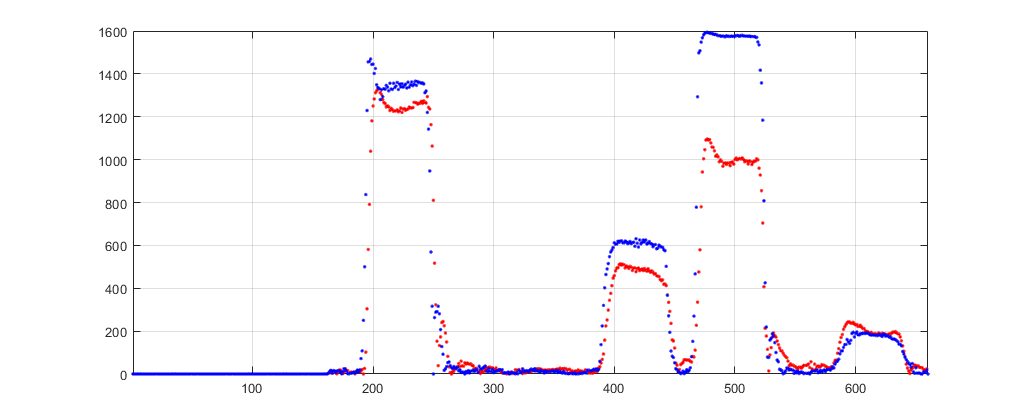

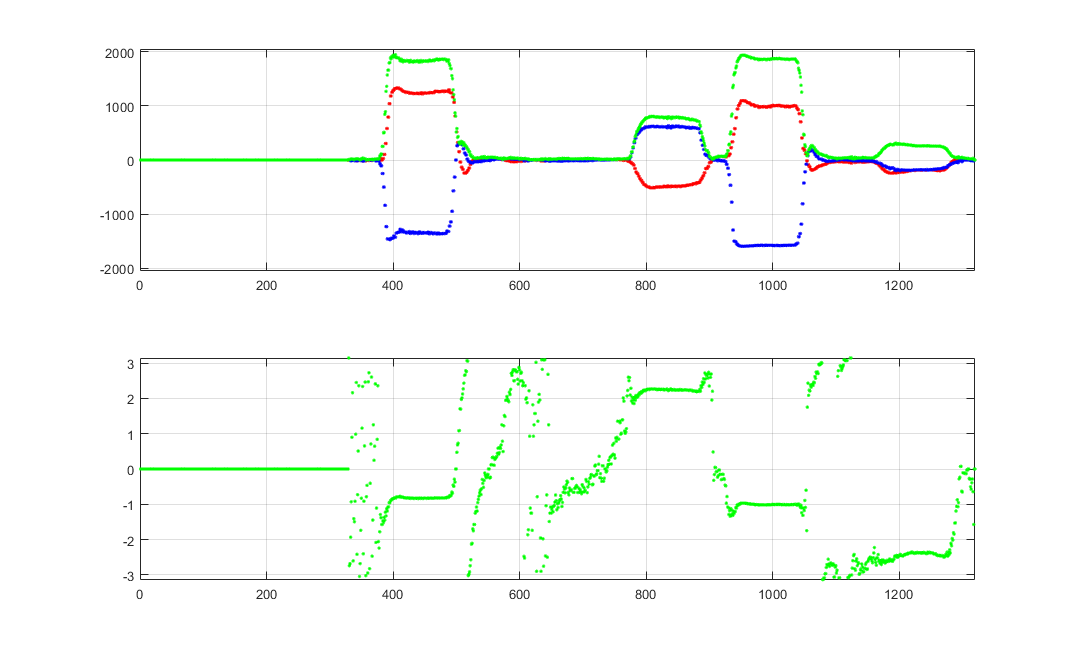

Как видно из рисунков после предлагаемой компенсации $A_0 \left(t\right)$ в комплексном сигнале отсутствуют колебания амплитуды и фазы. 

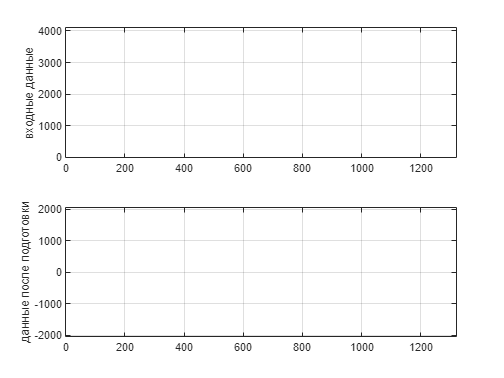

%% подготовка для тестирования и отображения результатом моделирования алгоритма
sound_velocity = sound_velocity_ini: ...
                 (sound_velocity_tgt-sound_velocity_ini)/(number_line-1): ...
                 sound_velocity_tgt;
sound_velocity_estimation_vkf4 = NaN(1,number_line);
sound_velocity_estimation_my   = NaN(1,number_line);
sound_velocity_estimation      = NaN(1,number_line);
sound_velocity_estimation_fi   = NaN(1,number_line);

figure;
  h_ax(1) = subplot(2, 1, 1);
    h_input_data = plot(1:length_line,NaN(1,length_line), '.g');
    grid on
    ylim(2 ^ ADC_WIDTH * [0 1])
    ylabel('входные данные')
  h_ax(2) = subplot(2, 1, 2);
    h_work_data = plot(1:length_line,NaN(1,length_line), '.g');
    hold on
    h_otr1 = line(NaN.* [1 1], 2 ^ (ADC_WIDTH - 1) .* [-1 1]);
    h_otr2 = line(NaN.* [1 1], 2 ^ (ADC_WIDTH - 1) .* [-1 1]);
    hold off
    grid on
    ylim(2 ^ (ADC_WIDTH - 1) * [-1 1])
    ylabel('данные после подготовки')
    xlim([1 length_line])
linkaxes(h_ax, 'x')


figure;
  h_axx(1) = subplot(3,1,[1 2]);
    %h_sv_etalon    = plot(1:number_line,sound_velocity, '.k');
    hold on
    h_sv_vkf4      = plot(1:number_line,NaN(1,number_line), 'or');
    h_sv_my        = plot(1:number_line,NaN(1,number_line), '.g');
    h_sv_matlab    = plot(1:number_line,NaN(1,number_line), 'ob');
    h_sv_matlab_fi = plot(1:number_line,NaN(1,number_line), '.c');
    legend('эталон', 'vkf4', 'xcoor\_my', 'matlab', 'matlab\_fi')

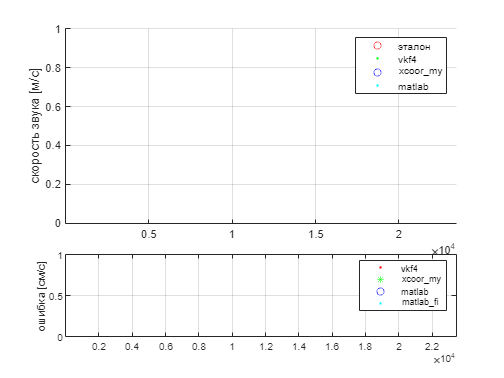

    hold off
    grid on
    ylabel('скорость звука [м/с]')
  h_axx(2) = subplot(3,1,3);
    h_err_sv_vkf4      = plot(1:number_line,NaN(1,number_line), '.r');
    hold on   
    h_err_sv_my        = plot(1:number_line,NaN(1,number_line), '*g');
    h_err_sv_matlab    = plot(1:number_line,NaN(1,number_line), 'ob');
    h_err_sv_matlab_fi = plot(1:number_line,NaN(1,number_line), '.c');
    legend('vkf4', 'xcoor\_my', 'matlab', 'matlab\_fi')
    hold off
    grid on
    ylabel('ошибка [см/с]')

linkaxes(h_axx, 'x')
xlim([1 number_line])


if (fl_plot_animation)
figure;
  h_ax_scl(1) = subplot(2,1,1);
    test_plots.h_real = plot(1:length_line,NaN(1,length_line),'.r');
    hold on
    test_plots.h_imag = plot(1:length_line,NaN(1,length_line),'.b');
    test_plots.h_abs = plot(1:length_line,NaN(1,length_line),'.g');
    hold off
    grid on
    ylim(2^(ADC_WIDTH-1)*[-1 1])
  h_ax_scl(2) = subplot(2,1,2);
    test_plots.h_angle = plot(1:length_line,NaN(1,length_line),'.g');
    grid on
    xlim([1 length_line])
    ylim(pi*[-1 1])
linkaxes(h_ax_scl, 'x')

reserve = 12; % запас
signal_size = 30 * (DATA_RATE / FREQUENCY_CENTRAL);
window_size = (signal_size + 4*reserve); % сигнал с хвостом
figure;
    test_plots.h_s1 = plot(0:window_size,NaN(1,window_size+1),'.r-');
    hold on
    test_plots.h_s2 = plot(0:window_size,NaN(1,window_size+1),'.b-');
    hold off
    grid on
    xlim([1 window_size])
    ylim([0 2^(ADC_WIDTH-1)])
    drawnow
end

if ~libisloaded('hydra_svm_math')
    [notfound, warnings] = loadlibrary('bin/hydra_svm_math.dll', ... 
                           'bin/hydra_svm_math.h', 'alias', 'hydra_svm_math');
end


% libfunctionsview hydra_svm_math
% libfunctions hydra_svm_math

otr1_ptr = libpointer('uint16Ptr', 0);
otr2_ptr = libpointer('uint16Ptr', 0);
xcorr_structure.index_time_propagation = uint16(0);
xcorr_structure.abs = single(1000);
xcorr_structure.phase = single(0);
xcorr_ptr = libstruct('Hydra_out_xcorr_t',xcorr_structure);
test_workmass_ptr = libpointer('int16Ptr', int16(zeros(1,length_line)));

for inx_line = 1:1:number_line
    % offset = double(mean(test_data(inx_line, :),2,"omitnan"));
    % test_mass = int16(test_data(inx_line, :) ) - offset - 0*round(xcorr_ptr.abs*0.03);
    % % test_mass(1:num_blank) = NaN;

    test_mass = int16(test_data(inx_line, :));
    test_workmass_ptr.Value = int16(test_mass);

## Получение комплексного сигнала

Сигнал на выходе АЦП - действительные выборки с часотой дискретизации равной $4\cdot f_0$.

Для получение комплексного сигнала используем умножение действительных выборок на $\sin \left(2\pi \cdot f_0 \cdot t\right)$ и $\cos \left(2\pi \cdot f_0 \cdot t\right)$. При частоте дискретизации равной $4\cdot f_0$, значения $\sin \left(2\pi \cdot f_0 \cdot t\right)$ и $\cos \left(2\pi \cdot f_0 \cdot t\right)$ представляют собой значения 1, 0 и -1, а комплексный сигнал можно получить соответствующей комбинацией действительных  отсчётов

                                        
$$\begin{array}{l}
\textrm{data}\_\textrm{complex}\left\lbrack \;i\;\right\rbrack \ldotp \textrm{Re}\;\;\;\;\;\;\;\;=\textrm{data}\_\textrm{real}\left\lbrack \;i\;\right\rbrack ;\\
\textrm{data}\_\textrm{complex}\left\lbrack \;i\;\right\rbrack \ldotp \textrm{Im}\;\;\;\;\;\;\;\;=\textrm{data}\_\textrm{real}\left\lbrack \;i+1\;\right\rbrack ;\\
\textrm{data}\_\textrm{complex}\left\lbrack \;i+1\;\right\rbrack \ldotp \textrm{Re}=-1*\textrm{data}\_\textrm{real}\left\lbrack \;i+2\;\right\rbrack ;\\
\textrm{data}\_\textrm{complex}\left\lbrack \;i+1\;\right\rbrack \ldotp \textrm{Im}=\textrm{data}\_\textrm{real}\left\lbrack \;i+1\;\right\rbrack ;\\
\textrm{data}\_\textrm{complex}\left\lbrack \;i+2\;\right\rbrack \ldotp \textrm{Re}=-1*\textrm{data}\_\textrm{real}\left\lbrack \;i+2\;\right\rbrack ;\\
\textrm{data}\_\textrm{complex}\left\lbrack \;i+2\;\right\rbrack \ldotp \textrm{Im}=-1*\textrm{data}\_\textrm{real}\left\lbrack \;i+3\;\right\rbrack ;\\
\textrm{data}\_\textrm{complex}\left\lbrack \;i+3\;\right\rbrack \ldotp \textrm{Re}=\textrm{data}\_\textrm{real}\left\lbrack \;i+4\;\right\rbrack ;\\
\textrm{data}\_\textrm{complex}\left\lbrack \;i+3\;\right\rbrack \ldotp \textrm{Im}=-1*\textrm{data}\_\textrm{real}\left\lbrack \;i+3\;\right\rbrack ;
\end{array}$$


Получаем комплексный сигнал, спектр которого смещён в 0.

## Выделение эхо-сигналов от дух мишеней

Нужно выделить эхо-сигнал от первой мишени $s_1$ и эхо-сигнал от второй мишени $s_2$. 

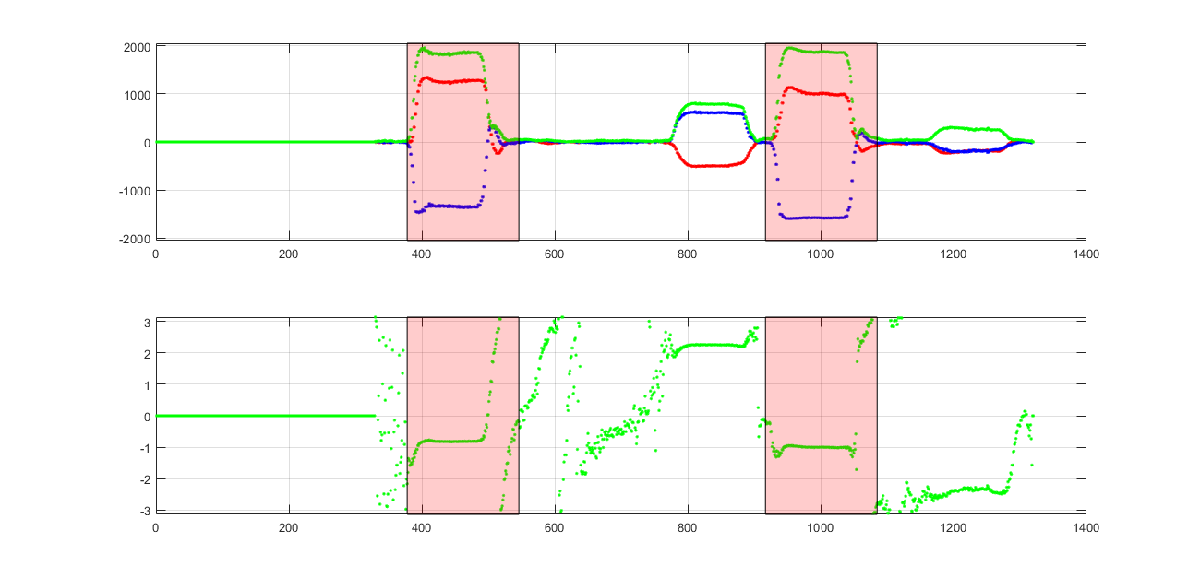

Сигналы $s_1$ и $s_2$ выборки комплексного сигнала, интервалы индексов 

[otr1 - reserve        otr1 - reserve + window_size] и 

[otr2 - 2*reserve    otr2 - 2*reserve + window_size] соответственно.

Здесь otr1 и otr2 индексы начала эхо-сигналов от мишеней,

           
$$\textrm{window}\_\textrm{size}=\left(\textrm{signal}\_\textrm{size}+4\cdot \textrm{reserve}\right)$$


            $\textrm{signal}\_\textrm{size}=N\cdot \left(\frac{f_s }{f_0 }\right)$,

            $N=30$ - число периодов несущей частоты $f_0$ в зондирующем импульсе ЗИ,

            $f_s$ - частота дискретизации.

В начале, когда мы не знаем скорость звука, (и, следовательно, индексы начала эхо-сигналов от мишеней) используем значения минимально $c_{\min } =1300\;\left\lbrack м\;/\;с\right\rbrack$ и максимально возможных $c_{\max } =1700\;\left\lbrack м\;/\;с\right\rbrack$ измеряемых скоростей распространения звука.

           $\textrm{otr1}=\textrm{floor}\left(2\cdot {\textrm{distance}}_1 \cdot \frac{f_s }{c_{\max } }\right)$,

$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{otr2}=\textrm{floor}\left(2\cdot {\textrm{distance}}_2 \cdot \frac{f_s }{c_{\max } }\right)$,

$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{window}\_{\textrm{size}}_1 =\textrm{ceil}\left(2\cdot {\textrm{distance}}_1 \cdot \frac{f_s }{c_{\min } }\right)-\textrm{otr1}+\textrm{signal}\_\textrm{size}$,

$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{window}\_{\textrm{size}}_2 =\textrm{ceil}\left(2\cdot {\textrm{distance}}_2 \cdot \frac{f_s }{c_{\min } }\right)-\textrm{otr2}+\textrm{signal}\_\textrm{size}$,

## Взаимная корреляция

Вычисляем взаимнокорреляционную функцию (ВКФ) комплексных выборок эхо-сигналов от двух мишененй ($\textrm{xcorr}\left(s_2 ,s_1 \right)$).

Мы специально смещаем окно второго сигнала влево (берём начальный индекс окна эхо-сигнала от второй мишени меньше на reserve), чтобы максимум ВКФ был в правой части (считаем только половину ВКФ).

ВКФ комплексные числа. По значениям индекса максимума амплитуды ***inx_max_xss*** и фазы в точке максимума ВКФ можно определить  задержку между эхо-сигналами ***time_propagation***.

Примерный вид выборок эхо-сигналов от мишеней, амплитуда и фаза их ВКФ представлены на рисунках ниже

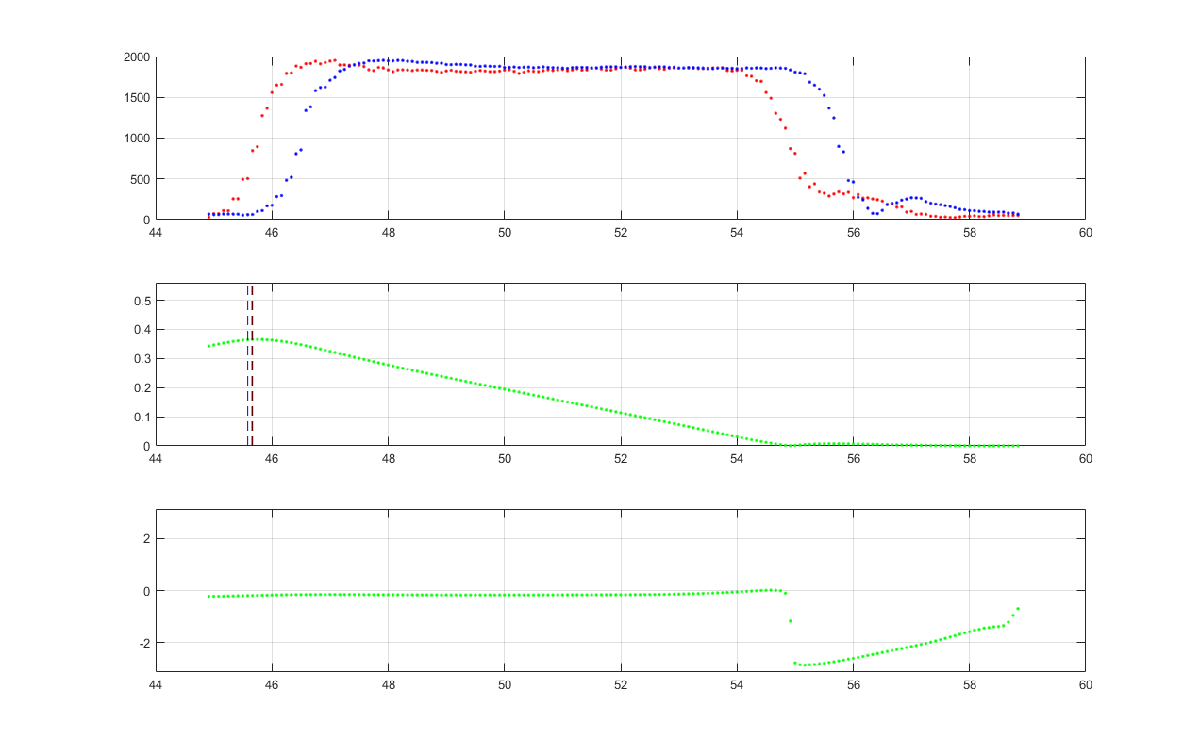

Задержка между эхо-сигналами от двух мишеней (время распространения сигнала на расстояние между мишенями 1 и 2)

         
$$\textrm{time}\_\textrm{propagation}=\left(M+\frac{\varphi }{2\cdot \pi }\right)\cdot \frac{1}{f_0 }$$


т.е. $M$ целых периодов центральной частоты ЗИ $f_0$ и ещё дробная частичка соответствующая фазе ВКФ $\varphi$.

(расстояние между мишенями составляет $M\cdot \lambda$  + $\frac{\varphi }{2\cdot \pi }\cdot \lambda$)

Задержка между эхо-сигналами от мишеней $\textrm{inx}\_\max$ в периодах частоты дискретизации $T_s =\frac{1}{f_s }$

          
$$\textrm{inx}\_\max =\textrm{otr2}-\textrm{otr1}+\left(\textrm{inx}\_\max \_\textrm{xss}-1\right)$$


          
$$\textrm{time}\_\textrm{xcorr}=\frac{\textrm{inx}\_\max }{f_s }$$


          
$$M=\textrm{floor}\left(\textrm{time}\_\textrm{xcorr}\cdot f_0 \right)$$


Существуют варианты, когда нужно $M$ дополнительно скорректировать

          
$$\begin{array}{l}
\textrm{if}\;\left(\;\left(\varphi <0\right)\;\&\;\left(\textrm{inx}\_\max -\textrm{fix}\_\textrm{num}\_\textrm{periods}\cdot 4>1\right)\;\right)\;\;\left|\right|\;\ldotp \ldotp \ldotp \\
\;\;\;\;\;\left(\left(\varphi <-\frac{\pi }{2}\right)\;\&\;\left(\textrm{inx}\_\max -\textrm{fix}\_\textrm{num}\_\textrm{periods}\cdot 4==1\right)\right)\;\;\left|\right|\;\;\ldotp \ldotp \ldotp \\
\;\;\;\;\;\left(\left(\varphi >=0\right)\;\&\;\left(\varphi <\frac{\pi }{2}\right)\;\;\&\;\left(\textrm{inx}\_\max -\textrm{fix}\_\textrm{num}\_\textrm{periods}\cdot 4==3\right)\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;M=M+1;\\
\textrm{end}
\end{array}$$


## Расчёт скорости распространения звука

Зная расстояние между мишенями $\textrm{base}={\textrm{distance}}_2 -{\textrm{distance}}_1$, находим скорость распространения звука

          
$$с=\frac{2\cdot \textrm{base}}{\textrm{time}\_\textrm{propagation}}$$


## Индексы начала эхо-сигналов от мишеней

          
$$\textrm{otr1}=\frac{2\cdot {\textrm{distance}}_1 }{c}\cdot f_s$$


          
$$\textrm{otr2}=\frac{2\cdot {\textrm{distance}}_2 }{c}\cdot f_s$$


## Уточнение $\textrm{inx}\_\max$

Существует проблема Эхо-сигналы от мишени 1 (красный) и 2 (синий) отличаются в первую очередь длительностью (см. рисунок ниже). Из-за это максимум ВКФ не является острым, поэтому ***inx_max*** от измерения к измерению может отличаться в интервале $\pm 2$. Из-за чего при определении количество целых периодов$M$в задержки между эхо-сигналами от мишеней может отличаться на 1 (что соответствует при существующей base ошибке в определении скеорости около 10 м/с). Это недопустимо много!!!

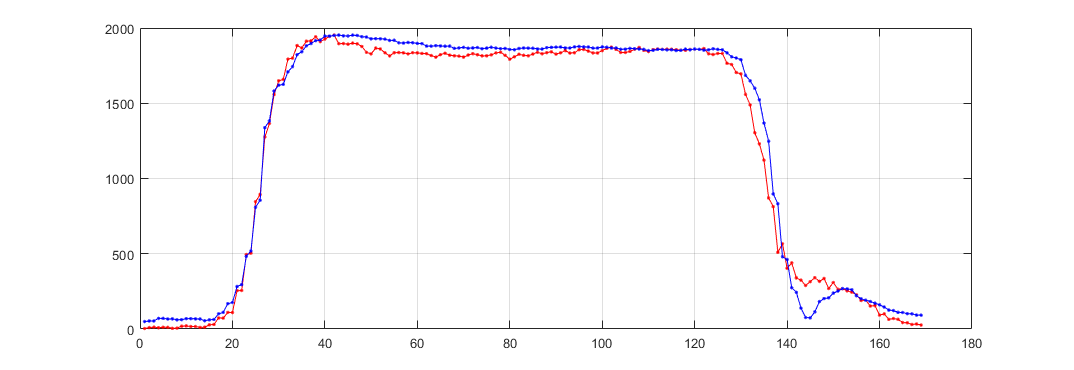

Предлагается уточний ***inx_max*** следующим образом:

Будем искать такую задержку, при которой передние фронты импульсов эхо-сигналов от мишеней наиболее близки.

Для этого используем выборки комплексного сигнала вблизи переднего фронта импульсов эхо-сигналов от мишеней

- первое окно ***as1 ***     $\left.\textrm{otr1}+\left\lbrack -\textrm{reserve}\;\ldotp \ldotp \ldotp \;\textrm{reserve}\right)\right\rbrack$    , имеем $\left(2\cdot \textrm{reserve}+1\right)$ комплексных отсчётов 

- второе окно ***as2***     $\left.\textrm{otr2}+\left\lbrack -2\cdot \textrm{reserve}\;\ldotp \ldotp \ldotp 2\cdot \textrm{reserve}\right)\right\rbrack$ , имеем $\left(4\cdot \textrm{reserve}+1\right)$ комплексных отсчётов

Рассчитываем амплитуды ***as1 ***и*** as2***

Из данных второго окна берём выборки $\textrm{as2}\left\lbrack 0:2\cdot \textrm{reserve}\right\rbrack$ и рассчитываем

для каждого $i$ ил интервала $\left\lbrack 0\;\;2\cdot \textrm{reserve}\right\rbrack$ рассчитываем сумму модулей разности

          
$$\textrm{xs}\left\lbrack i\right\rbrack =\sum_{j=0}^{2\cdot \textrm{reserve}} \left|\;s_1 \left\lbrack j\right\rbrack -{\mathrm{s}}_2 \left\lbrack i+j\right\rbrack \;\right|$$


Ищем минимум $\min \left(\textrm{xs}\right)$ индекс минимума соответствует ***inx_max.***

Пример поясняющий работу алгоритма расчёта уточнённого значения ***inx_max ***показан на рисунках ниже

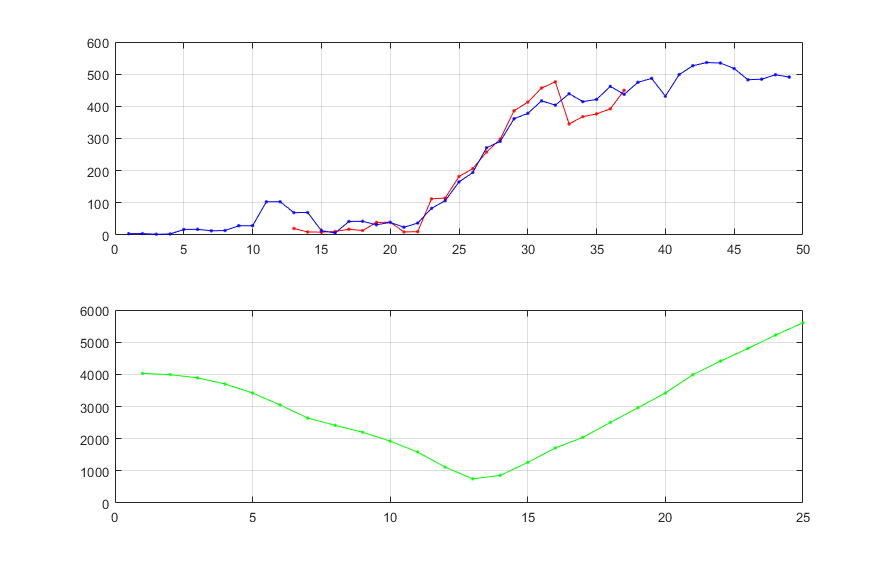

Описанный алгоритм был реализован и отлажен в [matlab](matlab:open('./hyperlink/crosscorrelation.m')).

Также был реализован в виде функций написанных на [C++](matlab:open('./hyperlink/hydra_svm_math.cpp')) (dll). 

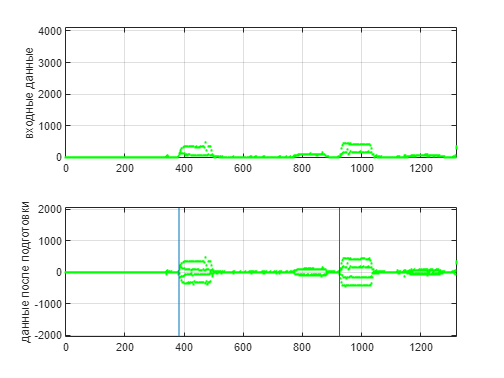

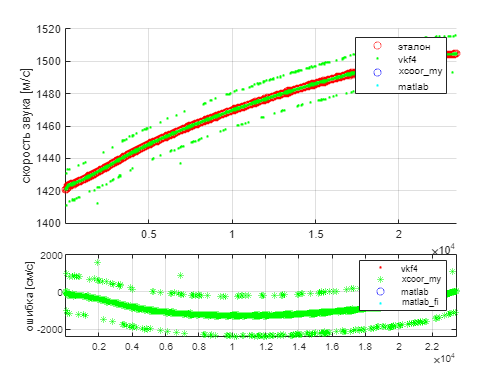

%% расчёт с ипользование кода dll
%tic
    sound_velocity_estimation_my(inx_line) = calllib('hydra_svm_math', 'hydra_svm', ...
                                test_workmass_ptr, base(1), base(2), otr1_ptr, otr2_ptr, xcorr_ptr);
%toc

%% расчёт в matlab    
    % [time_propagation, otr1_ptr.Value, otr2_ptr.Value] = ...
    %                     crosscorrelation (test_workmass_ptr.Value, base, ...
    %                                        otr1_ptr.Value, otr2_ptr.Value);
    % sound_velocity_estimation_vkf4(inx_line) = 2 * (base(2) - base(1)) ./ time_propagation;
    
    if (fl_plot_animation)
        test_otr (test_workmass_ptr.Value, otr1_ptr.Value, otr2_ptr.Value, test_plots);

        h_input_data.YData = test_mass;
        h_work_data.YData = get(test_workmass_ptr).Value;

        h_otr1.XData = double(otr1_ptr.Value) .* [1 1];
        h_otr2.XData = double(otr2_ptr.Value) .* [1 1];

        h_sv_vkf4.YData      = sound_velocity_estimation_vkf4;
        h_sv_my.YData        = sound_velocity_estimation_my;
        h_sv_matlab.YData    = sound_velocity_estimation;
        h_sv_matlab_fi.YData = sound_velocity_estimation_fi;

        h_err_sv_vkf4.YData      = (sound_velocity - sound_velocity_estimation_vkf4)*100;
        h_err_sv_my.YData        = (sound_velocity - sound_velocity_estimation_my)*100;
        h_err_sv_matlab.YData    = (sound_velocity - sound_velocity_estimation)*100;
        h_err_sv_matlab_fi.YData = (sound_velocity - sound_velocity_estimation_fi)*100;

        drawnow
    end
end

h_input_data.YData = test_mass;
h_work_data.YData = get(test_workmass_ptr).Value;

h_otr1.XData = double(otr1_ptr.Value) .* [1 1];
h_otr2.XData = double(otr2_ptr.Value) .* [1 1];

h_sv_vkf4.YData      = sound_velocity_estimation_vkf4;
h_sv_my.YData        = sound_velocity_estimation_my;
h_sv_matlab.YData    = sound_velocity_estimation;
h_sv_matlab_fi.YData = sound_velocity_estimation_fi;

h_sv_vkf4.YData = movmedian(sound_velocity_estimation_my,[ 5 5 ]);

h_err_sv_vkf4.YData      = (sound_velocity - sound_velocity_estimation_vkf4)*100;
h_err_sv_my.YData        = (sound_velocity - sound_velocity_estimation_my)*100;
h_err_sv_matlab.YData    = (sound_velocity - sound_velocity_estimation)*100;
h_err_sv_matlab_fi.YData = (sound_velocity - sound_velocity_estimation_fi)*100;

drawnow

clear all
unloadlibrary hydra_svm_math;